# Simscape multibody model og Regbot in balance

initial setup with motor velocity controller this is intended as simulation base for balance control.

close all
clear

## Simulink model name

model='regbot_1mg';

## parameters for REGBOT

motor

RA = 3.3/2;    % ohm (2 motors)
JA = 1.3e-6*2; % motor inertia
LA = 6.6e-3/2; % rotor inductor (2 motors)
BA = 3e-6*2;   % rotor friction
Kemf = 0.0105; % motor constant
Km = Kemf;
% køretøj
NG = 9.69; % gear
WR = 0.03; % wheel radius
Bw = 0.155; % wheel distance
%
% model parts used in Simulink
mmotor = 0.193;   % total mass of motor and gear [kg]
mframe = 0.32;    % total mass of frame and base print [kg]
mtopextra = 0.97 - mframe - mmotor; % extra mass on top (charger and battery) [kg]
mpdist =  0.10;   % distance to lit [m]
% disturbance position (Z)
pushDist = 0.1; % relative to motor axle [m]

## Own REGBOT parameters

% RA = 2*5.5;    % ohm (2 motors)
% JA = 0.0008+0.00055; % motor inertia
% LA = 6.6e-3/2; % rotor inductor (2 motors)
% BA = 0.00000132+0.00000420;   % rotor friction
% Kemf = (0.00782+0.00819)/2; % motor constant
% Km = Kemf;
% % køretøj
% NG = 9.69; % gear
% WR = 0.03; % wheel radius
% Bw = 0.155; % wheel distance
% % model parts used in Simulink
% mmotor = 0.193;   % total mass of motor and gear [kg]
% mframe = 0.32;    % total mass of frame and base print [kg]
% mtopextra = 0.97 - mframe - mmotor; % extra mass on top (charger and battery) [kg]
% mpdist =  0.10;   % distance to lit [m]
% % disturbance position (Z)
% pushDist = 0.1; % relative to motor axle [m]

## Controller design parameters

% Wheel velocity to voltage
N_i_vu = 2;
gamma_vu = 90;

% Tilt to velocity controller
N_i_tv = 10;
gamma_tv = 60;
alpha_tv = 0.00001;

% Pre velocity to tilt controller
N_i_vreft = 4;
gamma_vreft = 360+70;
alpha_vreft = 0.3;

% position to pre velocity controller
gamma_xvref = 360+80;
alpha_xvref = 0.3;

## Initial test parameters

x_test = 1;
x_size = 1;
v_size = 1;

## Sample controller values (initialisation)

K_vu = 15;     % Kp
t_i_vu = 0.05;   % Tau_i
Kffvu = 0;     % feed forward constant
startAngle = 10;  % tilt in degrees at time zero
twvlp = 0.005;    % velocity noise low pass filter time constant (recommended)
K_post = 1;
t_i_post = 1;
t_lead_tv = 0;
t_i_tv = 1;
K_tv = 1;
t_i_vreft = 1;
num_lead_vreft = 0;
den_lead_vreft = 1;
K_vreft = 1;
K_xvref = 1;
num_lead_xvref = 0;
den_lead_xvref = 1;

s = tf('s');

## Estimate transfer function for base system using LINEARIZE

Motor volatge to wheel velocity (wv)

load_system(model);
open_system(model);
% define points in model
ios(1) = linio(strcat(model,'/Limit9v'),1,'openinput');
ios(2) = linio(strcat(model, '/wheel_vel_filter'),1,'openoutput');
% attach to model
setlinio(model,ios);
% Use the snapshot time(s) 0 seconds
op = [0];
% Linearize the model
sys = linearize(model,ios,op);
% get transfer function
[num,den] = ss2tf(sys.A, sys.B, sys.C, sys.D);
Gvu = minreal(tf(num, den))

Gvu =
 
                  7.023e05 s^3 + 7.023e08 s^2 - 5.083e07 s - 5.083e10
  -----------------------------------------------------------------------------------
  s^6 + 2418 s^5 + 1.317e06 s^4 + 1.872e08 s^3 + 2.371e09 s^2 - 3.032e10 s - 1.881e11
 
Continuous-time transfer function.
Model Properties


## Transfer function from previous exercise

Gvu = tf([1.1775 1.68],[1 7.334 7.141]) 

Gvu =
 
     1.177 s + 1.68
  ---------------------
  s^2 + 7.334 s + 7.141
 
Continuous-time transfer function.
Model Properties


## Bodeplot

pole(Gvu)

ans =    -6.1782
   -1.1558


isstable(Gvu)

ans = logical
   1


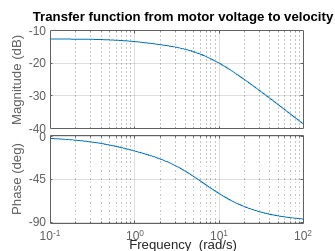

h = figure(100);
bode(Gvu)
grid on
title('Transfer function from motor voltage to velocity')

% saveas(h, 'motor to velocity.png');

## PI-Controller for voltage to velocity

% % Design parameters
% N_i = 4%N_i_vu;
% gamma_m = 100%gamma_vu;
% 
% phi_i = rad2deg(-atan(1/N_i));
% phi_G = -180+gamma_m-phi_i;
% 
% bode(Gvu)
% 
% [mag,phase,wout] = bode(Gvu);
% omega_c = interp1(squeeze(phase),wout,phi_G);
% tau_i = N_i/omega_c;
% C_i = tf([tau_i 1],[tau_i 0]);
% Kp = 1/abs(freqresp(C_i*Gvu,omega_c*1i));
% G_vu_ol = Kp*C_i*Gvu;
% G_vu_cl = G_vu_ol/(1+G_vu_ol);
% bode(G_vu_ol)
% step(G_vu_cl)

N_i = 3;
t_r = 0.2;

omega_c = 2.2/t_r;
tau_i = N_i/omega_c

tau_i = 0.2727

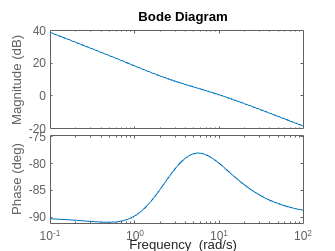

C_i = tf([tau_i 1],[tau_i 0]);
Kp = 1/abs(freqresp(C_i*Gvu,omega_c*1i));
G_vu_ol = Kp*C_i*Gvu;
G_vu_cl = G_vu_ol/(1+G_vu_ol);
bode(G_vu_ol)

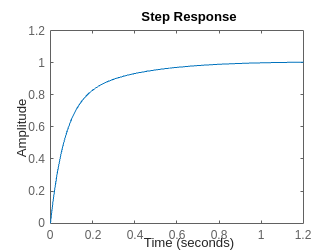

step(G_vu_cl)

## Flush values to model

K_vu = Kp

K_vu = 10.1357

t_i_vu = tau_i

t_i_vu = 0.2727

## **Transfer function from velocity to tilt using linearize**

% define points in model
ios(1) = linio(strcat(model,'/vel_cont'),1,'openinput');
ios(2) = linio(strcat(model, '/tilt_angle'),1,'openoutput');
% attach to model
setlinio(model,ios);
% Use the snapshot time(s) 0 seconds
op = [0];
% Linearize the model
sys = linearize(model,ios,op);
% get transfer function
[num,den] = ss2tf(sys.A, sys.B, sys.C, sys.D);
Gtv = minreal(tf(num, den))

Gtv =
 
                 -3.982e05 s^4 - 5.145e08 s^3 - 8.856e10 s^2 - 3.181e11 s - 9.517e08
  --------------------------------------------------------------------------------------------------
  s^7 + 2418 s^6 + 1.317e06 s^5 + 1.943e08 s^4 + 9.515e09 s^3 - 4.737e09 s^2 - 7.052e11 s - 1.889e12
 
Continuous-time transfer function.


h = figure(100)

h =   Figure (100) with properties:

      Number: 100
        Name: ''
       Color: [1 1 1]
    Position: [680 458 560 420]
       Units: 'pixels'

  Show all properties


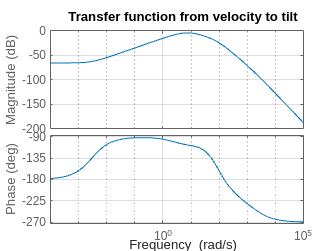

bode(-Gtv)
grid on
title('Transfer function from velocity to tilt')

[mag,phase,wout]=bode(Gtv);

## Post-Integrator

[gpeak,fpeak] = getPeakGain(-Gtv)

gpeak = 0.5823

fpeak = 7.5490

tau_i = 1/fpeak

tau_i = 0.1325

C_pi = -(tau_i*s+1)/(tau_i*s)

C_pi =
 
  -0.1325 s - 1
  -------------
    0.1325 s
 
Continuous-time transfer function.
Model Properties


G_post=Gtv*C_pi

G_post =
 
                5.274e04 s^5 + 6.855e07 s^4 + 1.225e10 s^3 + 1.307e11 s^2 + 3.182e11 s + 9.517e08
  -------------------------------------------------------------------------------------------------------------
  0.1325 s^8 + 320.4 s^7 + 1.744e05 s^6 + 2.574e07 s^5 + 1.26e09 s^4 - 6.275e08 s^3 - 9.342e10 s^2 - 2.502e11 s
 
Continuous-time transfer function.


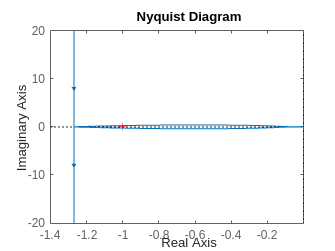

nyquist(G_post)

G_post_cl=minreal(G_post/(1+G_post))

G_post_cl =
 
                 3.982e05 s^5 + 5.175e08 s^4 + 9.244e10 s^3 + 9.866e11 s^2 + 2.402e12 s + 7.185e09
  ---------------------------------------------------------------------------------------------------------------
  s^8 + 2418 s^7 + 1.317e06 s^6 + 1.947e08 s^5 + 1.003e10 s^4 + 8.77e10 s^3 + 2.814e11 s^2 + 5.13e11 s + 7.185e09
 
Continuous-time transfer function.


isstable(G_post_cl)

ans = logical
   1


## Flush values to Simulink

K_post = -1

K_post = -1

t_i_post=tau_i

t_i_post = 0.1325

## Tilt to velocity controller PI-lead

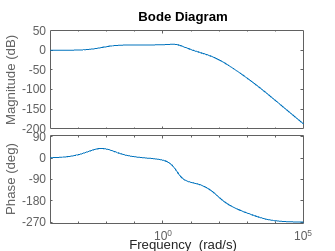

bode(G_post_cl)

% Design parameters
N_i =4%N_i_tv;

N_i = 4

gamma_m = 75%gamma_tv;

gamma_m = 75

alpha = 0.01%alpha_tv;

alpha = 0.0100



phi_i = rad2deg(-atan(1/N_i));
phi_m = rad2deg(asin((1-alpha)/(1+alpha)));

phi_G = gamma_m - phi_i - phi_m - 180;
[mag,phase,wout] = bode(G_post_cl);
omega_c = interp1(squeeze(phase),wout,phi_G);

tau_D = 1/(omega_c*sqrt(alpha));
tau_i = N_i/omega_c;

C_i = tf([tau_i 1],[tau_i 0])

C_i =
 
  0.03633 s + 1
  -------------
    0.03633 s
 
Continuous-time transfer function.
Model Properties


C_D = tf([tau_D 1], [tau_D*alpha 1])

C_D =
 
   0.09083 s + 1
  ---------------
  0.0009083 s + 1
 
Continuous-time transfer function.
Model Properties


[mag,phase] = bode((C_i*C_D*G_post_cl),omega_c);
Kp = 1/mag;

G_tv_ol = minreal(Kp*C_i*C_D*G_post_cl)

G_tv_ol =
 
            7.826e07 s^7 + 1.047e11 s^6 + 2.211e13 s^5 + 9.249e14 s^4 + 1.345e16 s^3 + 7.696e16 s^2 + 1.431e17 s + 4.279e14
  ------------------------------------------------------------------------------------------------------------------------------------
  s^10 + 3519 s^9 + 3.979e06 s^8 + 1.644e09 s^7 + 2.244e11 s^6 + 1.113e13 s^5 + 9.684e13 s^4 + 3.103e14 s^3 + 5.647e14 s^2 + 7.91e12 s
 
Continuous-time transfer function.


G_tv_cl = minreal(G_tv_ol/(1+G_tv_ol))

G_tv_cl =
 
                  7.826e07 s^7 + 1.047e11 s^6 + 2.211e13 s^5 + 9.249e14 s^4 + 1.345e16 s^3 + 7.696e16 s^2 + 1.431e17 s + 4.279e14
  ------------------------------------------------------------------------------------------------------------------------------------------------
  s^10 + 3519 s^9 + 3.979e06 s^8 + 1.723e09 s^7 + 3.291e11 s^6 + 3.325e13 s^5 + 1.022e15 s^4 + 1.376e16 s^3 + 7.752e16 s^2 + 1.431e17 s + 4.279e14
 
Continuous-time transfer function.


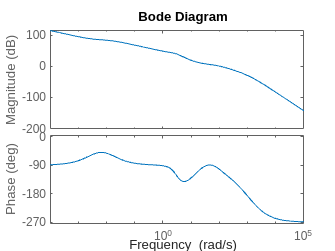


bode(G_tv_ol)

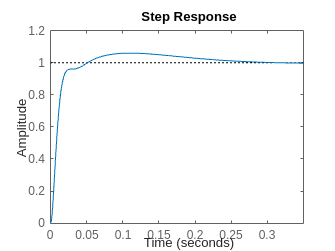

step(G_tv_cl)

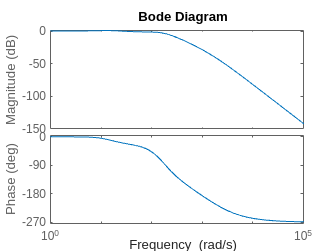

bode(G_tv_cl)

## Flush values to simulink

t_i_post

t_i_post = 0.1325

t_lead_tv = tau_D

t_lead_tv = 0.0908

t_i_tv = tau_i

t_i_tv = 0.0363

K_tv = Kp

K_tv = 1.9656

## Transfer function from reference tilt to velocity using linearize

% define points in model
ios(1) = linio(strcat(model,'/tilt_ref'),1,'openinput');
ios(2) = linio(strcat(model, '/wheel_vel_filter'),1,'openoutput');
% attach to model
setlinio(model,ios);
% Use the snapshot time(s) 0 seconds
op = [0];
% Linearize the model
sys = linearize(model,ios,op);
% get transfer function
[num,den] = ss2tf(sys.A, sys.B, sys.C, sys.D);
G_vreft = minreal(tf(num, den))

G_vreft =
 
                -1.399e07 s^6 - 1.453e10 s^5 - 5.458e11 s^4 - 3.666e12 s^3 + 2.891e13 s^2 + 3.414e14 s + 7.715e14
  -----------------------------------------------------------------------------------------------------------------------------
  s^9 + 2418 s^8 + 1.388e06 s^7 + 2.823e08 s^6 + 2.246e10 s^5 + 8.098e11 s^4 + 1.203e13 s^3 + 6.99e13 s^2 + 1.3e14 s + 3.887e11
 
Continuous-time transfer function.


## Reference tilt to velocity controller

isstable(G_vreft)

ans = logical
   1


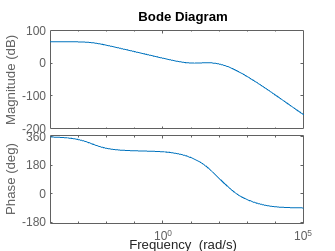

bode(G_vreft)



% Design parameters
N_i = 4%N_i_vreft;

N_i = 4

gamma_m = 70+360%gamma_vreft;

gamma_m = 430

alpha = 0.9 %alpha_vreft;

alpha = 0.9000



phi_i = rad2deg(-atan(1/N_i));
phi_m = rad2deg(asin((1-alpha)/(1+alpha)));

phi_G = gamma_m - phi_i - phi_m - 180;
[mag,phase,wout] = bode(G_vreft);
omega_c = interp1(squeeze(phase),wout,phi_G);

tau_D = 1/(omega_c*sqrt(alpha));
tau_i = N_i/omega_c;

C_i = tf([tau_i 1],[tau_i 0])

C_i =
 
  2.364 s + 1
  -----------
    2.364 s
 
Continuous-time transfer function.
Model Properties


C_D = tf([tau_D 1], [tau_D*alpha 1])

C_D =
 
  0.6231 s + 1
  ------------
  0.5608 s + 1
 
Continuous-time transfer function.
Model Properties


[mag,phase] = bode((C_i*C_D*G_vreft),omega_c);
Kp = 1/mag;

G_vreft_ol = minreal(Kp*C_i*C_D*G_vreft)

G_vreft_ol =
 
             -3.976e06 s^8 - 4.138e09 s^7 - 1.635e11 s^6 - 1.359e12 s^5 + 5.998e12 s^4 + 1.13e14 s^3 + 4.216e14 s^2 + 5.105e14 s + 1.488e14
  -----------------------------------------------------------------------------------------------------------------------------------------------------
  s^11 + 2420 s^10 + 1.392e06 s^9 + 2.848e08 s^8 + 2.296e10 s^7 + 8.498e11 s^6 + 1.347e13 s^5 + 9.135e13 s^4 + 2.547e14 s^3 + 2.322e14 s^2 + 6.932e11 s
 
Continuous-time transfer function.


G_vreft_cl = minreal(G_vreft_ol/(1+G_vreft_ol))

G_vreft_cl =
 
                   -3.976e06 s^8 - 4.138e09 s^7 - 1.635e11 s^6 - 1.359e12 s^5 + 5.998e12 s^4 + 1.13e14 s^3 + 4.216e14 s^2 + 5.105e14 s + 1.488e14
  ----------------------------------------------------------------------------------------------------------------------------------------------------------------
  s^11 + 2420 s^10 + 1.392e06 s^9 + 2.808e08 s^8 + 1.882e10 s^7 + 6.864e11 s^6 + 1.211e13 s^5 + 9.735e13 s^4 + 3.676e14 s^3 + 6.538e14 s^2 + 5.112e14 s + 1.488e14
 
Continuous-time transfer function.


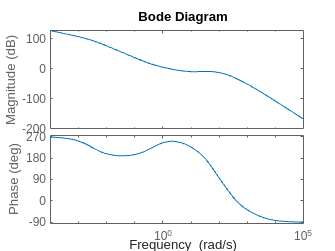


bode(G_vreft_ol)

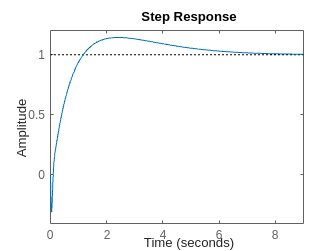

step(G_vreft_cl)

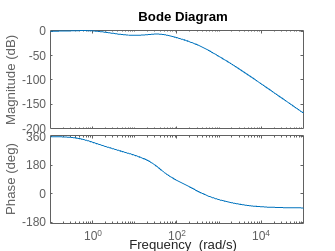

bode(G_vreft_cl)

min(abs(real(pole(G_vreft_cl))))

ans = 0.7353

omega_c

omega_c = 1.6918

## Flush values to simulink

t_i_vreft = tau_i

t_i_vreft = 2.3644

[num_lead_vreft,den_lead_vreft] = tfdata(C_D,'v')

num_lead_vreft =     0.6231    1.0000


den_lead_vreft =     0.5608    1.0000


K_vreft = Kp

K_vreft = 0.2558

## Transfer function from vel_pre to x

% define points in model
ios(1) = linio(strcat(model,'/vel_ref'),1,'openinput');
ios(2) = linio(strcat(model, '/x_pos'),1,'openoutput');
% attach to model
setlinio(model,ios);
% Use the snapshot time(s) 0 seconds
op = [0];
% Linearize the model
sys = linearize(model,ios,op);
% get transfer function
[num,den] = ss2tf(sys.A, sys.B, sys.C, sys.D);
G_xvref = minreal(tf(num, den))

G_xvref =
 
             -1.789e04 s^9 - 2.224e07 s^8 - 4.507e09 s^7 - 1.627e11 s^6 - 1.517e12 s^5 + 3.488e12 s^4 + 1.17e14 s^3 + 5.966e14 s^2 + 1.191e15 s + 8.32e14
  -------------------------------------------------------------------------------------------------------------------------------------------------------------------
  s^12 + 2420 s^11 + 1.392e06 s^10 + 2.879e08 s^9 + 2.597e10 s^8 + 7.167e11 s^7 + 1.133e13 s^6 + 9.203e13 s^5 + 3.77e14 s^4 + 8.678e14 s^3 + 1.239e15 s^2 + 8.32e14 s
 
Continuous-time transfer function.


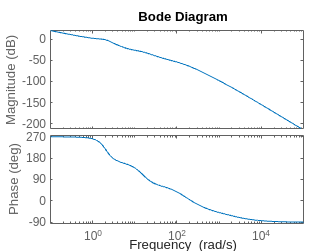

bode(G_xvref)

isstable(G_xvref)

ans = logical
   0


pole(G_xvref)

ans = 1.0e+03 *

   0.0000 + 0.0000i
  -1.6931 + 0.0000i
  -0.4275 + 0.0000i
  -0.1333 + 0.0770i
  -0.1333 - 0.0770i
  -0.0094 + 0.0126i
  -0.0094 - 0.0126i
  -0.0073 + 0.0000i
  -0.0036 + 0.0000i
  -0.0009 + 0.0019i




% Design parameters
gamma_m = 60+360%gamma_xvref;

gamma_m = 420

alpha = 0.9%alpha_xvref;

alpha = 0.9000


phi_m = rad2deg(asin((1-alpha)/(1+alpha)));

phi_G = gamma_m - phi_m - 180;
[mag,phase,wout] = bode(G_xvref);
omega_c = interp1(squeeze(phase),wout,phi_G);

tau_D = 1/(omega_c*sqrt(alpha));

C_D = tf([tau_D 1], [tau_D*alpha 1])

C_D =
 
  0.633 s + 1
  ------------
  0.5697 s + 1
 
Continuous-time transfer function.
Model Properties


[mag,phase] = bode((C_D*G_xvref),omega_c);
Kp = 1/mag;

G_xvref_ol = minreal(Kp*C_D*G_xvref)

G_xvref_ol =
 
             -1.924e04 s^10 - 2.394e07 s^9 - 4.884e09 s^8 - 1.826e11 s^7 - 1.908e12 s^6 + 1.172e12 s^5 + 1.317e14 s^4 + 8.402e14 s^3 + 2.294e15 s^2 + 2.917e15 s + 1.413e15
  ------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
  s^13 + 2422 s^12 + 1.396e06 s^11 + 2.904e08 s^10 + 2.648e10 s^9 + 7.622e11 s^8 + 1.259e13 s^7 + 1.119e14 s^6 + 5.385e14 s^5 + 1.529e15 s^4 + 2.762e15 s^3 + 3.007e15 s^2 + 1.46e15 s
 
Continuous-time transfer function.


G_xvref_cl = minreal(G_xvref_ol/(1+G_xvref_ol))

G_xvref_cl =
 
                    -1.924e04 s^14 - 2.422e07 s^13 - 5.229e09 s^12 - 2.542e11 s^11 - 4.854e12 s^10 - 3.9e13 s^9 - 2.16e12 s^8 + 2.556e15 s^7 + 2.314e16 s^6 + 1.084e17 s^5 + 3.112e17 s^4 + 5.661e17 s^3 + 6.376e17 s^2 + 4.062e17 s + 1.12e17
  ---------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
  s^17 + 2436 s^16 + 1.431e06 s^15 + 3.105e08 s^14 + 3.071e10 s^13 + 1.156e12 s^12 + 2.507e13 s^11 + 3.418e14 s^10 + 3.043e15 s^9 + 1.836e16 s^8 + 7.814e16 s^7 + 2.437e17 s^6 + 5.699e17 s^5 + 9.967e17 s^4 + 1.255e18 s^3 + 1.057e18 s^2 + 5.219e17 s + 1.12e17
 
Continuous-time transfer function.


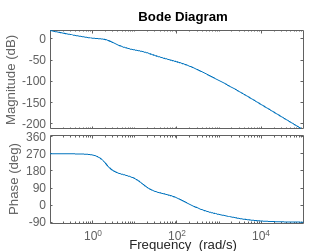


bode(G_xvref_ol)

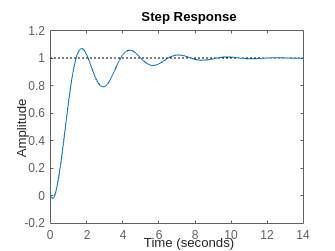

step(G_xvref_cl)

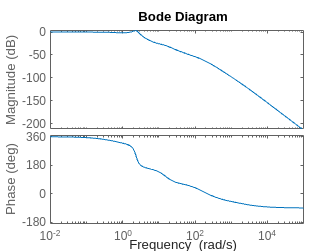

bode(G_xvref_cl)

[gpeak,fpeak] = getPeakGain(G_xvref_cl);
syms x0
tau_pre = double(vpasolve(abs(1/(x0*1i*fpeak+1)) == 1/gpeak));
G_pre = 1/(s*tau_pre+1)

G_pre =
 
       1
  ------------
  0.4633 s + 1
 
Continuous-time transfer function.
Model Properties


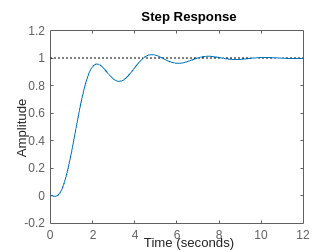

step(G_xvref_cl*G_pre)

## Flush values to Simulink

[num_lead_xvref,den_lead_xvref] = tfdata(C_D,'v')

num_lead_xvref =     0.6330    1.0000


den_lead_xvref =     0.5697    1.0000


K_xvref = Kp

K_xvref = 0.9677

tau_pre

tau_pre = 0.4633

## X step test

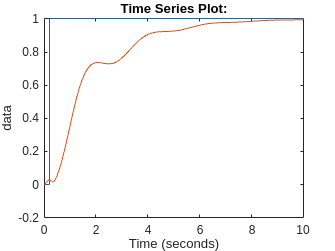

x_test = 1;
x_size = 1;

regsim = sim(model,10);

figure(1);
plot(regsim.ref);
hold on;
plot(regsim.x_pos);
hold off;

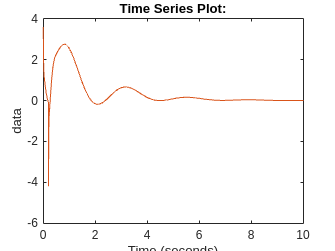


figure(2)
plot(regsim.u)
hold on;
plot(regsim.ulim);
hold off;

## v step size

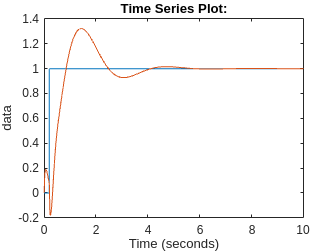

x_test = 0;
v_size = 1;

regsim = sim(model,10);

figure(1);
plot(regsim.vref);
hold on;
plot(regsim.vel);
hold off;

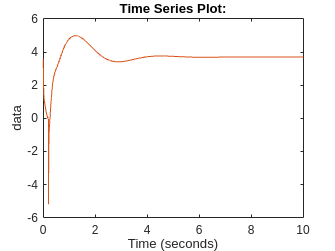


figure(2)
plot(regsim.u)
hold on;
plot(regsim.ulim);
hold off;

## Print controller values

K_vu

K_vu = 10.1357

t_i_vu

t_i_vu = 0.2727

K_post

K_post = -1

t_i_post

t_i_post = 0.1325

t_lead_tv

t_lead_tv = 0.0908

t_i_tv

t_i_tv = 0.0363

K_tv

K_tv = 1.9656

t_i_vreft

t_i_vreft = 2.3644

num_lead_vreft

num_lead_vreft =     0.6231    1.0000


den_lead_vreft

den_lead_vreft =     0.5608    1.0000


K_vreft

K_vreft = 0.2558

K_xvref

K_xvref = 0.7976

num_lead_xvref

num_lead_xvref =     0.7622    1.0000


den_lead_xvref

den_lead_xvref =     0.3049    1.0000


tau_pre

tau_pre = 0.2699